# State Observer Design for the Inverted Pendulum

State: x = [theta; theta_dot]

Measurement: y = C*x = theta

The observer reconstructs the full state using the measured angle and the discrete-time model.

## 1. Load / define the discrete-time model

model_available = exist('Ad','var') && ...
                  exist('Bd','var') && ...
                  exist('Ts','var');

if ~model_available

    % Standalone configuration used in Part 1
    m = 1;
    g = 9.8;
    l = 0.3;
    b = 0.1;

    J = m*l^2;
    Ts = 0.01;

    Ac = [0 1;
          m*g*l/J  -b/J];

    Bc = [0;
          1/J];

    sys_c = ss(Ac,Bc,eye(2),zeros(2,1));
    sys_d = c2d(sys_c,Ts,'zoh');

    Ad = sys_d.A;
    Bd = sys_d.B;

end

Ad

Ad =     1.0039    0.0200
    0.3921    0.9999


Bd

Bd =     0.0008
    0.0799


Ts

Ts = 0.0200

## 2. Measurement model

Only the angular position theta is measured. Therefore:

with C = [1 0].

C = [1 0];

## 3. Observability analysis

A full-order observer can reconstruct the complete state only if the pair (Ad,C) is observable.

O = obsv(Ad,C);
rank_O = rank(O)

rank_O = 2


assert(rank_O == 2, ...
    'The pair (Ad,C) is not observable.');
% Since the system has two states, observability requires rank(O) = 2.

## 4. Observer pole selection

The observer estimation error evolves according to

Hence, the observer poles are the eigenvalues of (Ad - L*C). For a discrete-time observer they must lie inside the unit circle.

observer_poles = [0.4 0.5];

assert(all(abs(observer_poles) < 1), ...
    'Discrete-time observer poles must lie inside the unit circle.');

## 5. Observer gain

L = place(Ad',C',observer_poles)';

L

L =     1.1038
   15.3983



% Verify the achieved observer poles.
eig_observer = eig(Ad - L*C)

eig_observer =     0.4000
    0.5000



% Initial state estimate for the Simulink Unit Delay
xhat0 = [0; 0];

## 6. Observer equation

The implemented observer is

The innovation term

is the difference between the measured output and the output predicted by the observer. It is used to correct the state estimate.

## 7. Basic observer simulation

We first test the observer independently of the LQR controller.

The true state and the observer start from different initial conditions. This allows us to verify whether the estimation error converges to zero.

Tsim = 0.5;
N = round(Tsim/Ts) + 1;

x = zeros(2,N);
xhat = zeros(2,N);

% True initial state
x(:,1) = [0.1; 0];

% Intentionally incorrect initial observer estimate
xhat(:,1) = [0; 0.5];

% Zero input for this first observer-only test
u = zeros(1,N);

for k = 1:N-1

    % Measured output: only theta
    y = C*x(:,k);

    % True discrete-time model
    x(:,k+1) = Ad*x(:,k) + Bd*u(k);

    % State observer
    xhat(:,k+1) = Ad*xhat(:,k) + Bd*u(k) ...
        + L*(y - C*xhat(:,k));
end

## 8. Compare true and estimated states

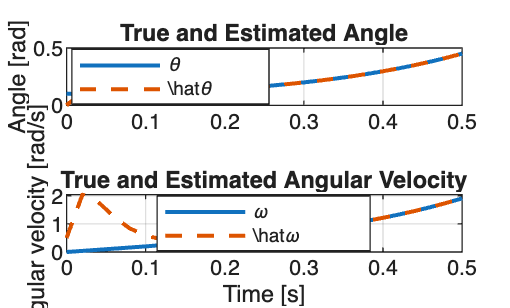

t = (0:N-1)*Ts;

figure;

subplot(2,1,1)
plot(t,x(1,:),'LineWidth',1.5)
hold on
plot(t,xhat(1,:),'--','LineWidth',1.5)
legend('\theta','\hat{\theta}','Location','best')
ylabel('Angle [rad]')
title('True and Estimated Angle')
grid on

subplot(2,1,2)
plot(t,x(2,:),'LineWidth',1.5)
hold on
plot(t,xhat(2,:),'--','LineWidth',1.5)
legend('\omega','\hat{\omega}','Location','best')
ylabel('Angular velocity [rad/s]')
xlabel('Time [s]')
title('True and Estimated Angular Velocity')
grid on

## 9. Estimation error

A correctly designed observer should satisfy

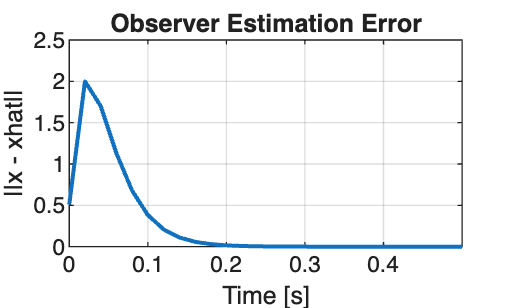

e = x - xhat;
error_norm = vecnorm(e);

figure
plot(t,error_norm,'LineWidth',1.5)
xlabel('Time [s]')
ylabel('||x - xhat||')
title('Observer Estimation Error')
grid on

xlim([0,0.5])

## Experiment 1 - Different observer poles

Compare slower and faster observer dynamics.

Poles closer to zero generally produce faster convergence in this ideal model, but aggressive observers can become more sensitive to measurement noise.

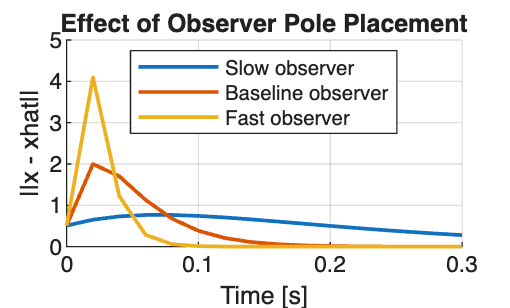

pole_sets = {
    [0.8 0.85], 'Slow observer';
    [0.4 0.5],  'Baseline observer';
    [0.1 0.2],  'Fast observer'
};

figure
hold on

for i = 1:size(pole_sets,1)

    poles_i = pole_sets{i,1};
    label_i = pole_sets{i,2};

    L_i = place(Ad',C',poles_i)';

    xhat_i = zeros(2,N);
    xhat_i(:,1) = [0; 0.5];

    for k = 1:N-1
        y = C*x(:,k);
        xhat_i(:,k+1) = Ad*xhat_i(:,k) + Bd*u(k) ...
            + L_i*(y - C*xhat_i(:,k));
    end

    e_i = x - xhat_i;
    plot(t,vecnorm(e_i),'LineWidth',1.4,'DisplayName',label_i)
end

xlabel('Time [s]')
ylabel('||x - xhat||')
title('Effect of Observer Pole Placement')
legend('Location','best')
grid on

xlim([0 0.3])

## Experiment 2 - Different initial observer estimates

Test whether the observer converges even when xhat(0) is far from x(0).

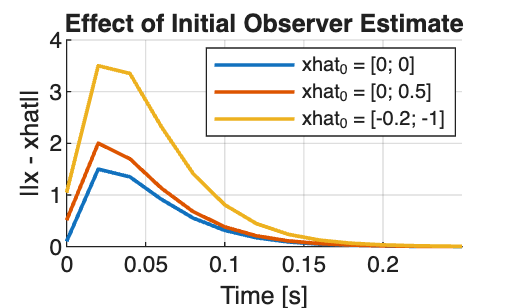

initial_estimates = {
    [0; 0],       'xhat_0 = [0; 0]';
    [0; 0.5],     'xhat_0 = [0; 0.5]';
    [-0.2; -1.0], 'xhat_0 = [-0.2; -1]'
};

figure
hold on

for i = 1:size(initial_estimates,1)

    xhat0_i = initial_estimates{i,1};
    label_i = initial_estimates{i,2};

    xhat_i = zeros(2,N);
    xhat_i(:,1) = xhat0_i;

    for k = 1:N-1
        y = C*x(:,k);
        xhat_i(:,k+1) = Ad*xhat_i(:,k) + Bd*u(k) ...
            + L*(y - C*xhat_i(:,k));
    end

    e_i = x - xhat_i;
    plot(t,vecnorm(e_i),'LineWidth',1.4,'DisplayName',label_i)
end

xlabel('Time [s]')
ylabel('||x - xhat||')
title('Effect of Initial Observer Estimate')
legend('Location','best')
grid on

xlim([0 0.25])

## Experiment 3 - Measurement noise

Add noise to the measured angle y = theta. This illustrates the trade-off between fast observer dynamics and noise sensitivity.

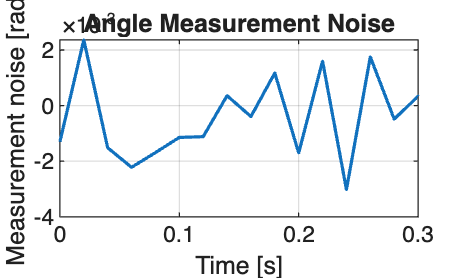

rng(1)
noise_std = 0.002;

xhat_noise = zeros(2,N);
xhat_noise(:,1) = [0; 0.5];

y_measured = zeros(1,N);

for k = 1:N-1

    y_measured(k) = C*x(:,k) + noise_std*randn;

    xhat_noise(:,k+1) = Ad*xhat_noise(:,k) + Bd*u(k) ...
        + L*(y_measured(k) - C*xhat_noise(:,k));
end

y_measured(N) = C*x(:,N) + noise_std*randn;

figure
plot(t, y_measured - x(1,:), 'LineWidth', 1.2)
xlabel('Time [s]')
ylabel('Measurement noise [rad]')
title('Angle Measurement Noise')
grid on
xlim([0 0.3])

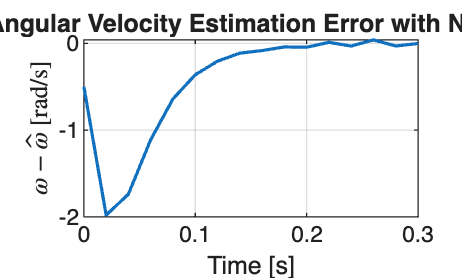


figure
plot(t, x(2,:) - xhat_noise(2,:), 'LineWidth', 1.2)
xlabel('Time [s]')
ylabel('$\omega - \hat{\omega}$ [rad/s]','Interpreter','latex')
title('Angular Velocity Estimation Error with Noise')
grid on
xlim([0 0.3])

## **Experiment 3.1 - Noise sensitivity for different observer poles**

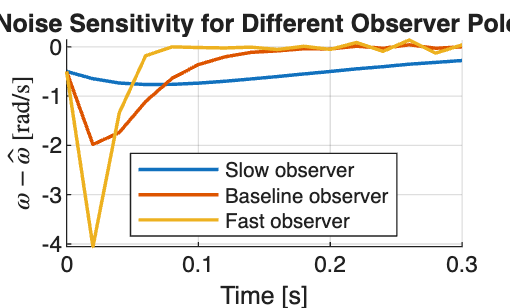


rng(1)                  % same noise every time
noise_std = 0.002;

pole_sets = {
    [0.8 0.85], 'Slow observer';
    [0.4 0.5],  'Baseline observer';
    [0.1 0.2],  'Fast observer'
    };

% generate ONE noisy measurement sequence
y_noisy = zeros(1,N);

for k = 1:N
    y_noisy(k) = C*x(:,k) + noise_std*randn;
end

figure
hold on

for i = 1:size(pole_sets,1)

    poles_i = pole_sets{i,1};
    label_i = pole_sets{i,2};

    L_i = place(Ad',C',poles_i)';

    xhat_i = zeros(2,N);
    xhat_i(:,1) = [0; 0.5];

    for k = 1:N-1
        xhat_i(:,k+1) = Ad*xhat_i(:,k) + Bd*u(k) ...
            + L_i*(y_noisy(k) - C*xhat_i(:,k));
    end

    omega_error = x(2,:) - xhat_i(2,:);

    plot(t,omega_error,'LineWidth',1.3,'DisplayName',label_i)
end

xlabel('Time [s]')
ylabel('$\omega - \hat{\omega}$ [rad/s]','Interpreter','latex')
title('Noise Sensitivity for Different Observer Poles')
legend('Location','best')
grid on
xlim([0 0.3])

## 13. Alternative angular velocity estimation

A simple alternative is finite-difference differentiation:

This method is easy but strongly amplifies measurement noise.

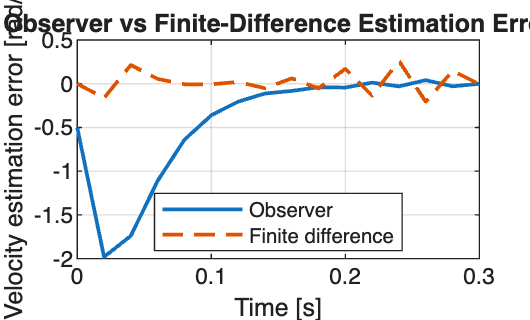

omega_fd = zeros(1,N);

for k = 2:N
    omega_fd(k) = (y_measured(k) - y_measured(k-1))/Ts;
end

observer_error = x(2,:) - xhat_noise(2,:);
fd_error = x(2,:) - omega_fd;

figure
plot(t, observer_error, 'LineWidth', 1.4)
hold on
plot(t, fd_error, '--', 'LineWidth', 1.4)

xlabel('Time [s]')
ylabel('Velocity estimation error [rad/s]')
title('Observer vs Finite-Difference Estimation Error')
legend('Observer','Finite difference','Location','best')
grid on
xlim([0 0.3])

## **Experiment 4 - Sampling time**

The sampling time affects the discrete-time model and therefore also the observer dynamics.

For each sampling time, the same continuous-time plant is discretized again and a new observer gain is computed.

To make the comparison fair, approximately the same observer dynamics in continuous time are preserved.

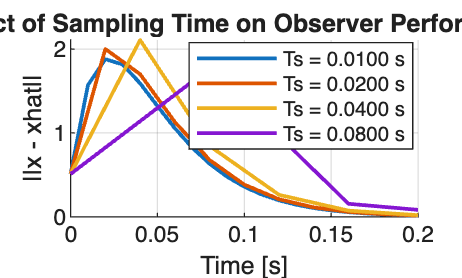


% Reconstruct the continuous-time model corresponding to
% the current Ad, Bd and Ts.

sys_d_base = ss(Ad,Bd,eye(2),zeros(2,1),Ts);
sys_c_base = d2c(sys_d_base,'zoh');


Ts_values = [Ts/2, Ts, 2*Ts, 4*Ts];

% Convert the baseline discrete observer poles into
% equivalent continuous-time rates

observer_rates = log(observer_poles)/Ts;

Tsim_sampling = 0.5;

x0_sampling = [0.1; 0];
xhat0_sampling = [0; 0.5];

figure
hold on

for i = 1:length(Ts_values)

    Ts_i = Ts_values(i);

    % Discretize the same physical model using the new sampling time
    sys_d_i = c2d(sys_c_base,Ts_i,'zoh');

    Ad_i = sys_d_i.A;
    Bd_i = sys_d_i.B;

    observer_poles_i = exp(observer_rates*Ts_i);

    L_i = place(Ad_i',C',observer_poles_i)';

    N_i = round(Tsim_sampling/Ts_i) + 1;

    x_i = zeros(2,N_i);
    xhat_i = zeros(2,N_i);

    x_i(:,1) = x0_sampling;
    xhat_i(:,1) = xhat0_sampling;

    % Zero input: isolate observer behaviour
    u_i = zeros(1,N_i);

    for k = 1:N_i-1

        y_i = C*x_i(:,k);

        % True system
        x_i(:,k+1) = Ad_i*x_i(:,k) + Bd_i*u_i(k);

        % Observer
        xhat_i(:,k+1) = Ad_i*xhat_i(:,k) + Bd_i*u_i(k) ...
            + L_i*(y_i - C*xhat_i(:,k));

    end

    t_i = (0:N_i-1)*Ts_i;

    e_i = x_i - xhat_i;

    plot(t_i,vecnorm(e_i), ...
        'LineWidth',1.4, ...
        'DisplayName',sprintf('Ts = %.4f s',Ts_i));

end

xlabel('Time [s]')
ylabel('||x - xhat||')
title('Effect of Sampling Time on Observer Performance')
legend('Location','best')
grid on
xlim([0,0.2])